#### Jared Ham

MECH 513 - Simulation and Modeling

HW4 - Monte Carlo

### Task 1: Using Monte Carlo to Calculate Pi

Pi is calculated using two methods:

- Classical Monte Carlo: Picks 4 completely random numbers at each iteration

- Latin Hypercube Sampling: Picks 4 random numbers at each iteration, however it ensures that it picks one in each quadrant

A circle of radius 0.5 is placed inside of a 2x2 square. Each random number can be tested as to whether or not it is inside the square. The ratio of points that should be inside the square is:

    
$$\frac{A_{\mathrm{circle}} }{A_{\mathrm{square}} }=\frac{\pi *{\left(0\ldotp 5\right)}^2 }{4}=\frac{\pi }{16}$$


This means that the value of pi can be calculated as:

    
$$\pi =16*\frac{#_{\mathrm{inside}} }{#_{\mathrm{outside}} }\;$$


Below is code from Dr. Bradley that runs the monte carlo simulation to estimate the value of pi. 

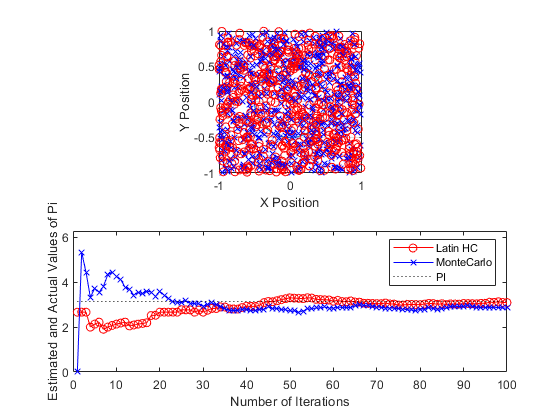

clear ; close all
figure;
ang = [0:.1:2*pi];
r = .5;
subplot(2,1,1)
plot(r*cos(ang),r*sin(ang))
grid
axis([-1 1 -1 1 ])
axis equal
axis square
hold on
%Iterative Loop
k_lhc = 0;
k_mc = 0;
lhc_squares = 6^2;
max_fun_calls = 100;
n_divisions = sqrt(lhc_squares);
for n_fun_calls = 1:max_fun_calls

 %Latin Hypercube
 lhs_i_index = randperm(sqrt(lhc_squares));
 lhs_j_index = randperm(sqrt(lhc_squares));

 for i=lhs_i_index;
 lower_border = -1+((i-1)*2/n_divisions);
 upper_border = -1+((i)*2/n_divisions);
 x_pos = lower_border + (upper_border-lower_border).*rand(1);

 for j=lhs_j_index(i)
 lower_border = -1+((j-1)*2/n_divisions);
 upper_border = -1+((j)*2/n_divisions);
 y_pos = lower_border + (upper_border-lower_border).*rand(1);

 subplot(2,1,1);plot(x_pos,y_pos,'ro'); xlabel('X Position'); ylabel('Y Position')
 k_lhc=k_lhc+1;
 inside_lhc(k_lhc) = sqrt(x_pos^2 + y_pos^2) <= r;
 end
 end
 pi_lhc(n_fun_calls) = 16*sum(inside_lhc)/length(inside_lhc) ;
 subplot(2,1,2); plot(pi_lhc,'ro-'); hold on ;

 %MonteCarlo
 for i=1:sqrt(lhc_squares)
 x_pos_mc = 2*(rand(1)-.5);
 y_pos_mc = 2*(rand(1)-.5);
 subplot(2,1,1);plot(x_pos_mc,y_pos_mc,'bx')
 k_mc=k_mc+1;
 inside_mc(k_mc) = sqrt(x_pos_mc^2 + y_pos_mc^2) <= r;
 end

 pi_mc(n_fun_calls) = 16*sum(inside_mc)/length(inside_mc) ;

 subplot(2,1,2); plot(pi_mc,'bx-');
 plot([1:max_fun_calls],ones(1,max_fun_calls)*pi,'k:')
 hold off;
 axis([0 max_fun_calls 0 2*pi ])
 xlabel('Number of Iterations')
 ylabel('Estimated and Actual Values of Pi')
 legend('Latin HC','MonteCarlo','PI')


 pause(.1)

end

### Task 2: Simulation of Uncertaintity using Monte Carlo Techniques

Given the power vs wind curve for a wind turbine shown below, predict the average and standard deviation of the wind turbine power output assuming the wind speed follows a Rayleigh distrubution with an average wind speed of 4 m/s. 

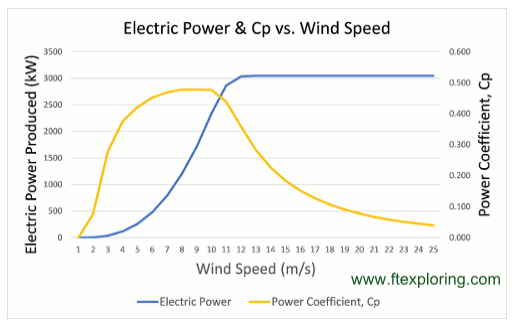

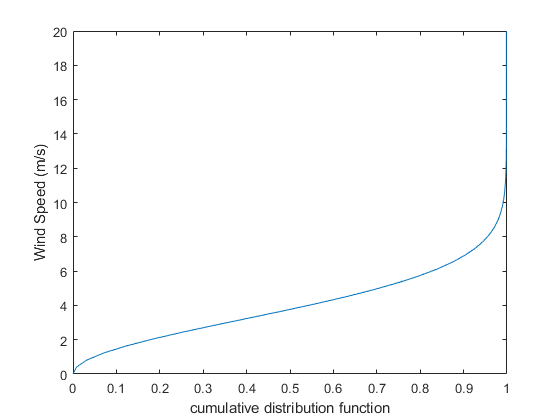

figure;
u_bar = 4;
u_wind = linspace(0,20,50);
c = 2*u_bar/sqrt(pi);
rayleigh_pdf = 2*u_wind / (c^2) .* exp(-(u_wind./c).^2);
rayleigh_cdf = cumtrapz(u_wind, rayleigh_pdf);

plot(rayleigh_cdf, u_wind)
xlabel('cumulative distribution function');
ylabel('Wind Speed (m/s)')

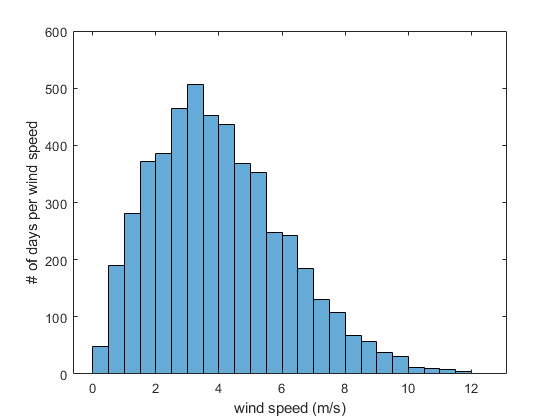


num_iterations = 1000;
num_samples = 5;
wind_speed_each_day = zeros(num_iterations, num_samples);
for sample_number = 1:num_samples
    for n=1:num_iterations
        wind_speed_each_day(n, sample_number) = interp1(rayleigh_cdf, u_wind, rand(1,1));
    end
end

histogram(wind_speed_each_day)
xlabel("wind speed (m/s)");
ylabel("# of days per wind speed");

P = min(2.3*wind_speed_each_day.^3, 3000); % this approximates the power vs wind speed curve shown above
mean(P)

ans =   280.0298  301.1766  269.0550  288.2212  299.8397


std(P)

ans =   447.6712  433.7832  419.9261  403.4586  444.0924


### Task 4 - Homework

1) What is the average and standard deviation for the output power of the wind turbine in a location where the wind speed is a Rayleigh distribution with mean wind speed is 4m/s? Demonstrate convergence by reporting the average and standard deviation of turbine output power as the average of fiveN-sample Monte Carlo simulations, where N =10, 100, 1000. 

P_10_average = mean(P(1:10, :), 'all')

P_10_average = 302.1531

P_100_average = mean(P(1:100, :), 'all')

P_100_average = 304.4962

P_1000_average = mean(P(1:1000, :), 'all')

P_1000_average = 287.6645